Impedance control characterization based on $x_e(t)$, $\dot{x}_e(t)$ and $f(t)$. 2º Order $Z(s)$ and sinusoidal input.

close all
clear 
clc

% Fo = force input amplitude
% w_u = force input freq (ang)
% Impedance parameters: K, D, M -> w_n = sqrt(K/M), zeta = D/(2*M*w_n)
syms s t Fo w_u w_n zeta K w_d
% Assumptions: simplifies the computation and avoid complex numbers
assume([t w_u w_n zeta K], {'real','positive'}), assume(Fo, 'real'), assume(zeta <= 1)
assume(w_d == w_n*sqrt(1 - zeta^2))
Es = (w_n^2)/(w_n^2 + 2*zeta*w_n*s + s^2)*(Fo * w_u/(s^2 + w_u^2))/K

$$Es = \frac{\mathrm{Fo}\,{w_{n}}^{2}\,w_{u}}{K\,\left(s^{2}+{w_{u}}^{2}\right)\,\left(s^{2}+2\,\zeta \,s\,w_{n}+{w_{n}}^{2}\right)}$$

Et = ilaplace(Es);

x_expr = latex(simplify(Et));

dEt = ilaplace(s*Es);
dx_expr = latex(simplify(dEt));

% to compute the gradient:
ddEt = ilaplace(s^2*Es);
ddx_expr = latex(simplify(ddEt));


## Parametric curve (ellipse) {e(t), de(t), f(t)}

assume(exp(-t*w_n*zeta) == 0) % from inspection on the original functions on t
Et  = simplify(Et);
dEt = simplify(dEt);
ddEt= simplify(ddEt);

Ft = Fo*sin(w_u*t);
Grad = [dEt, ddEt, diff(Ft, t)];             % Gradient Vect
Tang = [ddEt, diff(ddEt,t), diff(Ft, t, 2)]; % Tangent  Vect
N = cross(Grad, Tang);                       % Normal Vector
N = simplify(N)

$$N = \begin{array}{l} \left(\begin{array}{ccc} \frac{{\mathrm{Fo}}^{2}\,{w_{n}}^{2}\,{w_{u}}^{4}\,\left({w_{n}}^{2}-{w_{u}}^{2}\right)}{K\,\sigma_{1}} & \frac{2\,{\mathrm{Fo}}^{2}\,{w_{n}}^{3}\,{w_{u}}^{4}\,\zeta }{K\,\sigma_{1}} & -\frac{{\mathrm{Fo}}^{2}\,{w_{n}}^{4}\,{w_{u}}^{4}}{K^{2}\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={w_{n}}^{4}+4\,{w_{n}}^{2}\,{w_{u}}^{2}\,\zeta^{2}-2\,{w_{n}}^{2}\,{w_{u}}^{2}+{w_{u}}^{4} \end{array}$$

n_expr = latex(N);

Then, the normal vector can be simply defined as:

n_vec = [(w_n^2 - w_u^2) 2*zeta*w_n -w_n^2/K]

$$n\_vec = \left(\begin{array}{ccc} {w_{n}}^{2}-{w_{u}}^{2} & 2\,w_{n}\,\zeta & -\frac{{w_{n}}^{2}}{K} \end{array}\right)$$

% Considering Tx, and Ty sequential rotations:
assume([t w_u w_n zeta K], {'real','positive'}), assume(Fo, 'real'), assume(zeta <= 1)
phi = asin(-n_vec(1)/norm(n_vec)); % minus due to right hand rule
tht = atan(-n_vec(2)/n_vec(3));
%syms phi tht real
Tx  = [1 0 0; 0 cos(tht) -sin(tht); 0 sin(tht) cos(tht)];
Ty  = [cos(phi) 0 sin(phi); 0 1 0; -sin(phi) 0 cos(phi)];

Proj = (Tx*Ty)' * [Et dEt Ft]';
Proj = simplify(Proj);
Proj = collect(Proj, [cos(t*w_u) sin(t*w_u)]); % separate cos(t*w_u), and sin(t*w_u) coefficients

% Then, the Rot matrix is (from inspection of Proj):
R11 = (- (2*Fo*w_n^3*w_u*zeta*(1 - (w_n^2 - w_u^2)^2/(abs(w_n^2 - w_u^2)^2 + 4*w_n^2*abs(zeta)^2 + w_n^4/K^2))^(1/2))/(K*(w_n^4 + 4*w_n^2*w_u^2*zeta^2 - 2*w_n^2*w_u^2 + w_u^4)) - (2*Fo*w_n*w_u*zeta*(w_n^2 - w_u^2)^2)/(((4*K^2*zeta^2)/w_n^2 + 1)^(1/2)*(abs(w_n^2 - w_u^2)^2 + 4*w_n^2*abs(zeta)^2 + w_n^4/K^2)^(1/2)*(w_n^4 + 4*w_n^2*w_u^2*zeta^2 - 2*w_n^2*w_u^2 + w_u^4)));
R12 = ((Fo*(w_n^2 - w_u^2))/(((4*K^2*zeta^2)/w_n^2 + 1)^(1/2)*(abs(w_n^2 - w_u^2)^2 + 4*w_n^2*abs(zeta)^2 + w_n^4/K^2)^(1/2)) + (Fo*w_n^2*(w_n^2 - w_u^2)*(1 - (w_n^2 - w_u^2)^2/(abs(w_n^2 - w_u^2)^2 + 4*w_n^2*abs(zeta)^2 + w_n^4/K^2))^(1/2))/(K*(w_n^4 + 4*w_n^2*w_u^2*zeta^2 - 2*w_n^2*w_u^2 + w_u^4)) - (4*Fo*w_n^2*w_u^2*zeta^2*(w_n^2 - w_u^2))/(((4*K^2*zeta^2)/w_n^2 + 1)^(1/2)*(abs(w_n^2 - w_u^2)^2 + 4*w_n^2*abs(zeta)^2 + w_n^4/K^2)^(1/2)*(w_n^4 + 4*w_n^2*w_u^2*zeta^2 - 2*w_n^2*w_u^2 + w_u^4)));
R21 = ((Fo*w_n^3*w_u*(w_n^2 - w_u^2))/(K*(4*zeta^2*K^2 + w_n^2)^(1/2)*(w_n^4 + 4*w_n^2*w_u^2*zeta^2 - 2*w_n^2*w_u^2 + w_u^4)));
R22 = ((2*Fo*K*zeta)/(4*zeta^2*K^2 + w_n^2)^(1/2) + (2*Fo*w_n^4*w_u^2*zeta)/(K*(4*zeta^2*K^2 + w_n^2)^(1/2)*(w_n^4 + 4*w_n^2*w_u^2*zeta^2 - 2*w_n^2*w_u^2 + w_u^4)));

dw = w_n^2 - w_u^2; % TODO: simplification not working yet.
R_proj = (1/Fo)*[R11 R12; R21 R22];
      
N = abs(det(R_proj));
M = R_proj(1,1)^2 + R_proj(2,1)^2 + R_proj(1,2)^2 + R_proj(2,2)^2;
N = simplify(N);
M = simplify(M);
a_x = simplify( 1/2*(sqrt(M + 2*N) + sqrt(M - 2*N)) );
b_x = simplify( 1/2*(sqrt(M + 2*N) - sqrt(M - 2*N)) );

f1 = R_proj(:,1);
f2 = R_proj(:,2);
cot_2t0 = (f1'*f1 - f2'*f2)/(2*f1'*f2);
cot_2t0 = simplify(cot_2t0);
%Tz = [R_proj [0 0]'; 0 0 1];

## Plotting

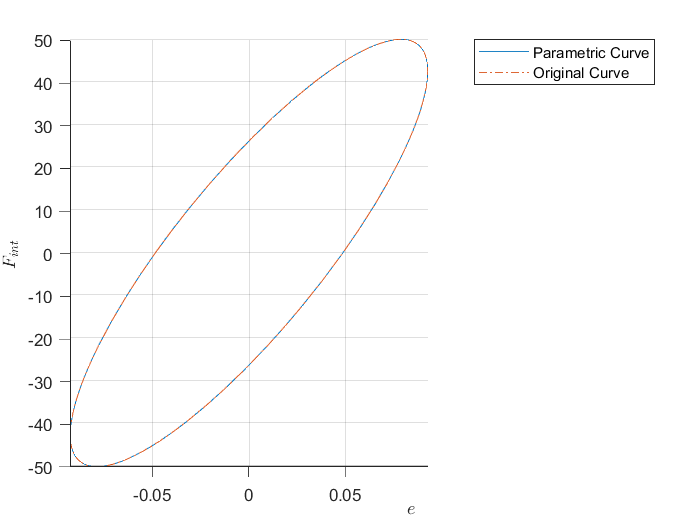

val_Fo  = 50;
val_freq = 0.31831;      % => 2 rad/s
val_wu = 2*pi*val_freq;
Kd = 500; Dd = 2*sqrt(Kd); Md = 10;
val_k = Kd;
val_wn = sqrt(Kd/Md);
val_zt = 1; %Dd/(2*Md*val_wn);
values = [val_Fo val_wu val_wn val_zt val_k];

T  = double( subs(Tx*Ty,  [w_u w_n zeta K], [val_wu val_wn val_zt val_k]) );
Rp = double( subs(R_proj, [Fo w_u w_n zeta K], values) );
Tz = [Rp [0 0]'; 0 0 1];

X = T*Tz*[val_Fo*cos(val_wu*t), val_Fo*sin(val_wu*t), 0]'; %Tz contains a & b
fplot3(X(1), X(2), X(3), [0 1/val_freq])
hold on

E = subs(Et, [Fo w_u w_n zeta K], values);
dE = subs(dEt, [Fo w_u w_n zeta K], values);
F = subs(Ft, [Fo w_u], [val_Fo val_wu]);
fplot3(E, dE, F, [0 1/val_freq],'-.')
xlabel('$e$',"Interpreter","latex")
ylabel('$\dot{e}$',"Interpreter","latex")
zlabel('$F_{int}$',"Interpreter","latex")
legend('Parametric Curve','Original Curve')
view([0.1 0.2])
hold off

val_Fo   = 50.0; % [N]
val_wu   = 3.00; % [Hz]
val_freq = val_wu/(2*pi); % [rad/s]

Inspecting how the curve changes according to $w_n$, $\zeta$, and $K$:

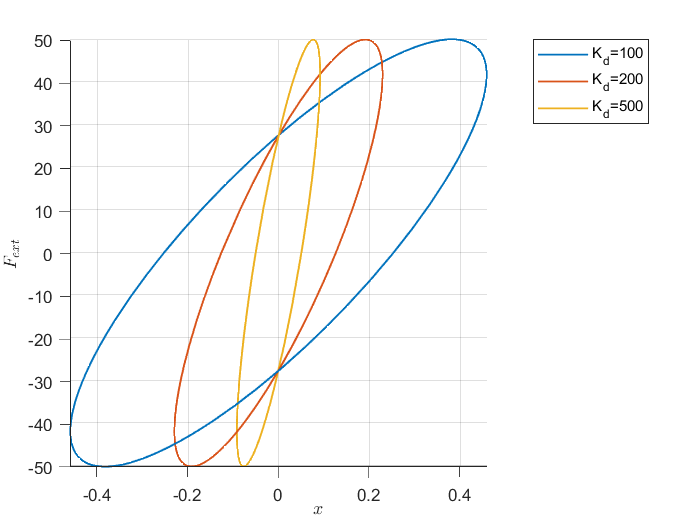

% Varying K
kd_array = [100 200 500];
figure
for Kd = kd_array
    val_k = Kd;
    val_wn = 10.0; % sqrt(Kd/Md);
    val_zt = 1;  % Dd/(2*Md*val_wn);
    values = [val_Fo val_wu val_wn val_zt val_k];
    
    T  = double( subs(Tx*Ty,  [w_u w_n zeta K], [val_wu val_wn val_zt val_k]) );
    Rp = double( subs(R_proj, [Fo w_u w_n zeta K], values) );
    Tz = [Rp [0 0]'; 0 0 1];
    
    % Parametric curve using the Transformations Tx*Ty*Tz
    X = T*Tz*[val_Fo*cos(val_wu*t), val_Fo*sin(val_wu*t), 0]'; %Tz contains a & b
    fplot3(X(1), X(2), X(3), [0 1/val_freq], 'LineWidth', 1.0, ...
           'DisplayName', strcat('K_d= ', num2str(Kd)))
    hold on
end

xlabel('$x$',"Interpreter","latex")
ylabel('$\dot{x}$',"Interpreter","latex")
zlabel('$F_{ext}$',"Interpreter","latex")
legend('show')
view([0.1 0.2])
hold off

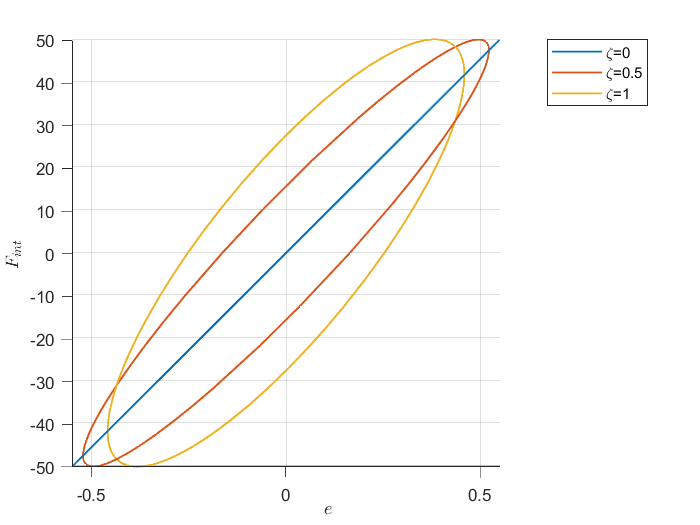

% Varying Zeta
zt_array = [0 0.5 1];
figure
for zt = zt_array
    val_k  = 100;
    val_wn = 10.0; % sqrt(Kd/Md);
    val_zt = zt;  % Dd/(2*Md*val_wn);
    values = [val_Fo val_wu val_wn val_zt val_k];
    
    T  = double( subs(Tx*Ty,  [w_u w_n zeta K], [val_wu val_wn val_zt val_k]) );
    Rp = double( subs(R_proj, [Fo w_u w_n zeta K], values) );
    Tz = [Rp [0 0]'; 0 0 1];
    
    % Parametric curve using the Transformations Tx*Ty*Tz
    X = T*Tz*[val_Fo*cos(val_wu*t), val_Fo*sin(val_wu*t), 0]';
    fplot3(X(1), X(2), X(3), [0 1/val_freq], 'LineWidth', 1.0, ...
           'DisplayName', strcat('\zeta= ', num2str(zt)))
    hold on
end

xlabel('$e$',"Interpreter","latex")
ylabel('$\dot{e}$',"Interpreter","latex")
zlabel('$F_{int}$',"Interpreter","latex")
legend('show')
view([0.1 0.2])
hold off

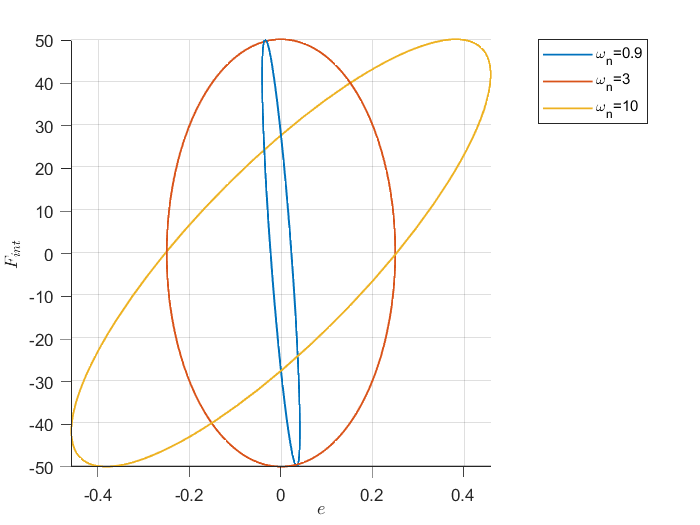

% Varying w_n
wn_array = [0.9 3 10];
figure
for wn = wn_array
    val_k  = 100;
    val_wn = wn; % sqrt(Kd/Md);
    val_zt = 1.0;  % Dd/(2*Md*val_wn);
    values = [val_Fo val_wu val_wn val_zt val_k];
    
    T  = double( subs(Tx*Ty,  [w_u w_n zeta K], [val_wu val_wn val_zt val_k]) );
    Rp = double( subs(R_proj, [Fo w_u w_n zeta K], values) );
    Tz = [Rp [0 0]'; 0 0 1];
    
    % Parametric curve using the Transformations Tx*Ty*Tz
    X = T*Tz*[val_Fo*cos(val_wu*t), val_Fo*sin(val_wu*t), 0]'; %Tz contains a & b
    fplot3(X(1), X(2), X(3), [0 1/val_freq], 'LineWidth', 1.0, ...
           'DisplayName', strcat('\omega_n= ', num2str(wn)))
    hold on
end

xlabel('$e$',"Interpreter","latex")
ylabel('$\dot{e}$',"Interpreter","latex")
zlabel('$F_{int}$',"Interpreter","latex")
legend('show')
view([0.1 0.2])
hold off

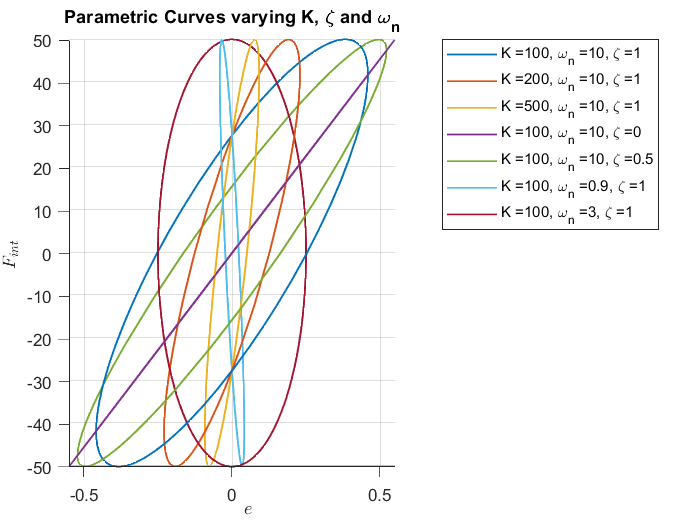

params_mtx = [100 1 10; 200 1.0 10; 500 1 10.0;...
              100 0 10; 100 0.5 10; 100 1 0.90; 100 1 3];
figure
for i = 1:7
    val_k  = params_mtx(i,1);
    val_zt = params_mtx(i,2);
    val_wn = params_mtx(i,3);
    values = [val_Fo val_wu val_wn val_zt val_k];
    
    T  = double( subs(Tx*Ty,  [w_u w_n zeta K], [val_wu val_wn val_zt val_k]) );
    Rp = double( subs(R_proj, [Fo w_u w_n zeta K], values) );
    Tz = [Rp [0 0]'; 0 0 1];
    
    % Parametric curve using the Transformations Tx*Ty*Tz
    X = T*Tz*[val_Fo*cos(val_wu*t), val_Fo*sin(val_wu*t), 0]'; %Tz contains a & b
    fplot3(X(1), X(2), X(3), [0 1/val_freq], 'LineWidth', 1.0, 'DisplayName', ...
           [strcat('K = ',        num2str(val_k)) ', ' ...
            strcat('\omega_n = ', num2str(val_wn)) ', ' ...
            strcat('\zeta = ',    num2str(val_zt))])
    hold on
end
title('Parametric Curves varying K, \zeta and \omega_n')
xlabel('$e$',"Interpreter","latex")
ylabel('$\dot{e}$',"Interpreter","latex")
zlabel('$F_{int}$',"Interpreter","latex")
legend('show')
view([0.1 0.2])
hold off

%% Using M, D, K:
syms Md Dd
assume([Md Dd], {'real','positive'})
w_n = sqrt(K/Md);
zeta = Dd/(2*Md*w_n);
n_vec = [(w_n^2 - w_u^2) 2*zeta*w_n -w_n^2/K]

$$n\_vec = \left(\begin{array}{ccc} \frac{K}{\mathrm{Md}}-{w_{u}}^{2} & \frac{\mathrm{Dd}}{\mathrm{Md}} & -\frac{1}{\mathrm{Md}} \end{array}\right)$$

% Simplyfing n, one can see:
n_vec = [(K - w_u^2*Md) Dd -1]

$$n\_vec = \left(\begin{array}{ccc} K-\mathrm{Md}\,{w_{u}}^{2} & \mathrm{Dd} & -1 \end{array}\right)$$

phi = asin(-n_vec(1)/norm(n_vec)) % minus due to right hand rule

$$phi = -\mathrm{asin}\left(\frac{K-\mathrm{Md}\,{w_{u}}^{2}}{\sqrt{{\mathrm{Dd}}^{2}+{\left|K-\mathrm{Md}\,{w_{u}}^{2}\right|}^{2}+1}}\right)$$

tht = atan(-n_vec(2)/n_vec(3))

$$tht = \mathrm{atan}\left(\mathrm{Dd}\right)$$

Tx  = [1 0 0; 0 cos(tht) -sin(tht); 0 sin(tht) cos(tht)];
Ty  = [cos(phi) 0 sin(phi); 0 1 0; -sin(phi) 0 cos(phi)];
